# Simulink demos

## Scenario setup

% Start the simulator.
beamng = py.beamngpy.BeamNGpy('localhost', int32(64256));
% beamng = py.beamngpy.BeamNGpy('localhost', int32(64256), home='/path/to/BeamNG.drive');

beamng.open();

% Create a vehicle.
vehicle = py.beamngpy.Vehicle('etk800', ...
    pyargs('model', 'etkc', 'licence', 'BeamNG', 'color', 'Black'));

% Create a scenario.
scenario = py.beamngpy.Scenario('west_coast_usa', 'simulink', ...
    pyargs('description', 'Matlab/Simulink bridge demo'));

scenario.add_vehicle(vehicle)
scenario.make(beamng)
beamng.load_scenario(scenario)
beamng.start_scenario()

vehicle.teleport(py.tuple([-335, 611, 76]), py.tuple([0, 0, 1, 0.4]));

## Demos' data

% demo 1 data: double line change
demo(1).x1 = -920;
demo(1).x2 = -870;
demo(1).x3 = -820;
demo(1).x4 = -770;
demo(1).y1 = 870;
demo(1).y2 = 875;
demo(1).v_target = 50/3.6;

% demo 2 data: brake test
demo(2).y = 767;
demo(2).v_target = 80/3.6;
demo(2).x1 = -920;
demo(2).x2 = -700;

% demo 3 data: interactive
demo(3).torque_gain = 3000;
demo(3).torque_gain_brake = - 5000;
demo(3).torque_bias = 18000;
demo(3).torque_rate = 400;

## Demo 0

mode = 0; %#ok
pause(0.5)
vehicle.ai.set_mode("span")
load_lua_controller(vehicle, false);
out = sim('beamng_simulink_interface_demos.slx');

Connection opened at time: 0.000000


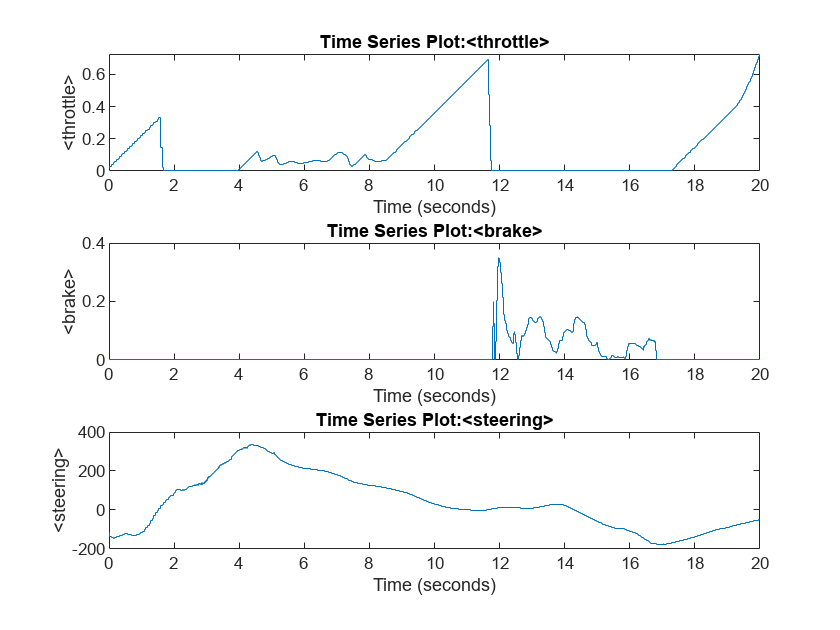

vehicle.ai.set_mode("disable")
pause(1)
beamng.restart_scenario();

% plot result
figure
subplot 311
plot(out.throttle0)
subplot 312
plot(out.brake0)
subplot 313
plot(out.steering0)

## Demo 1

mode = 1; %#ok
vehicle.teleport(py.tuple([-920, 870, 75]), py.tuple([0, 0, 1, -1]));
pause(0.5)
load_lua_controller(vehicle, false);
out = sim('beamng_simulink_interface_demos.slx');

Connection opened at time: 0.000000


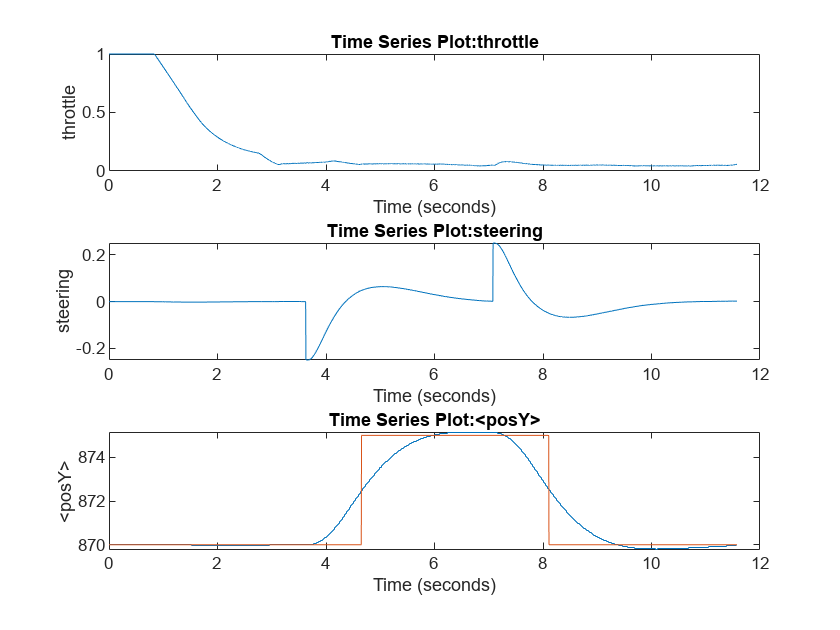

beamng.restart_scenario();

% plot result
figure
subplot 311
plot(out.throttle1)
subplot 312
plot(out.steering1)
subplot 313
plot(out.posy1)
hold on
plot(out.targety1)

## Demo 2

mode = 2; %#ok
vehicle.teleport(py.tuple([-920, 767, 92.5]), py.tuple([0, 0, 1, -1]));
pause(0.5)
load_lua_controller(vehicle, false);
out = sim('beamng_simulink_interface_demos.slx');

Connection opened at time: 0.000000


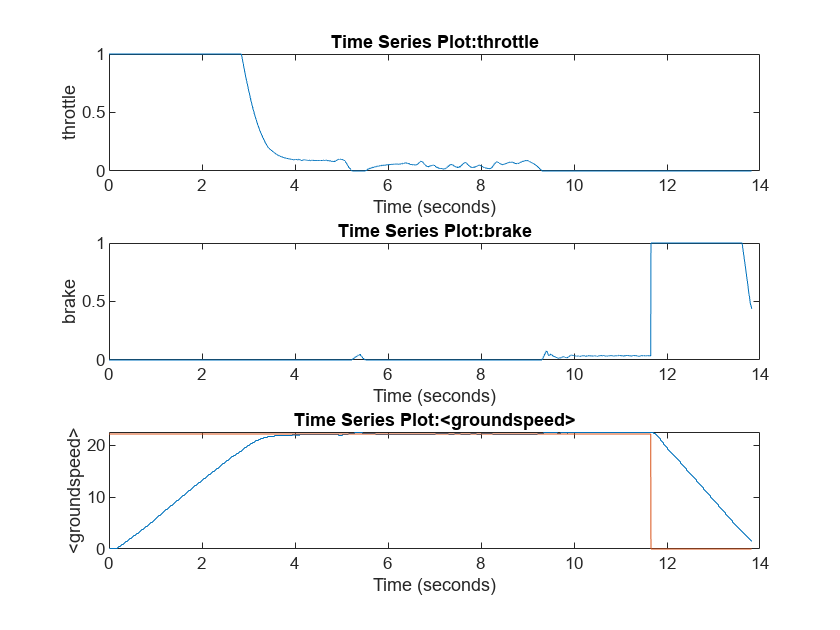

beamng.restart_scenario();

% plot result
figure
subplot 311
plot(out.throttle2)
subplot 312
plot(out.brake2)
subplot 313
plot(out.v2)
hold on
plot(out.targetv2)

## Demo 3

mode = 3;
vehicle.teleport(py.tuple([-318, 371, 101.5]), py.tuple([0, 0, 1, 0.4]));
pause(0.5)
vehicle.ai.set_mode("span")
load_lua_controller(vehicle, false);
out = sim('beamng_simulink_interface_demos.slx');

Connection opened at time: 0.000000


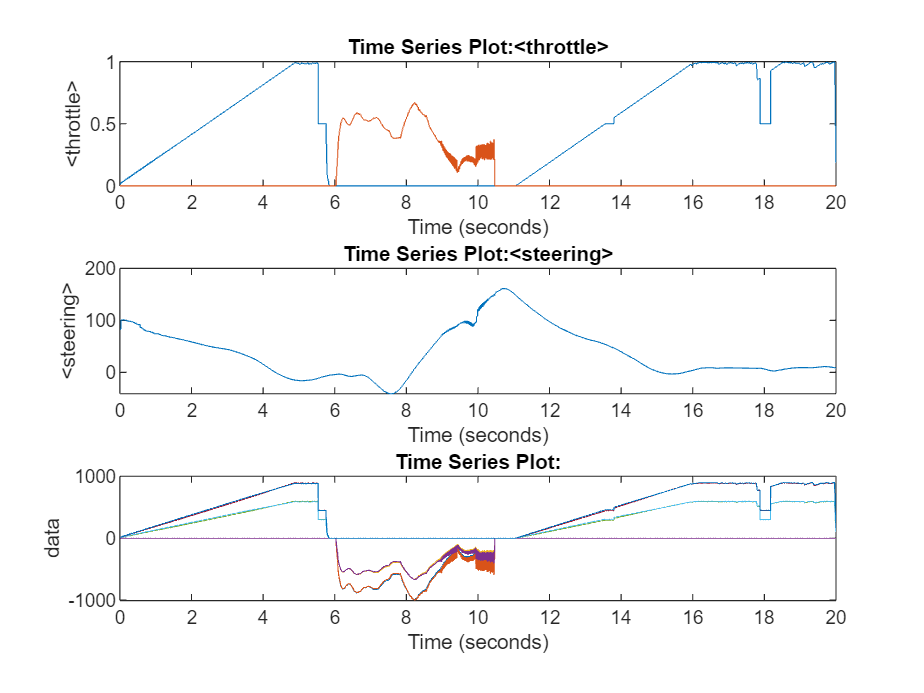

vehicle.ai.set_mode("disable")
pause(1)
beamng.restart_scenario();

% plot result
figure
subplot 311
plot(out.throttle3)
hold on
plot(out.brake3)
subplot 312
plot(out.steering3)
subplot 313
plot(out.torques3)

beamng.close()